# 124 adaptation

## load data

load("/Volumes/Elements/l24kg.mat");

## save data

save("/Volumes/Elements/l24kg.mat");

%124 LD 

k = 64;        

cd("/Volumes/Elements/Gallman/1212LD/Ferdie12-Oct-20-2021-A/");

k = 65;        

cd("/Volumes/Elements/Gallman/1212LD/Lydia12-Oct-21-2021-C/");

k = 66;

cd("/Volumes/Elements/Gallman/1212LD/Cheshire12-Oct-20-2021-D/");

k = 67;       

cd("/Volumes/Elements/Gallman/1212LD/Paco12-Oct-20-2021-E/");

k = 68;       

cd("/Volumes/Elements/Gallman/124LD/Cheshire124-Nov-03-2021-D/");

k = 69;       

cd("/Volumes/Elements/Gallman/124LD/Paco124-Nov-03-2021-E/");

k = 70;      

cd("/Volumes/Elements/Gallman/124LD/Ferdie124-Nov-03-2021-A/");

k = 71;

cd("/Volumes/Elements/Gallman/124LD/Lydia124-Nov-04-2021-C/");

k = 72;       

cd("/Volumes/Elements/Gallman/124LD/Cheshire124-Nov-18-2021-D/");

k = 73;

cd("/Volumes/Elements/Gallman/124LD/Ferdie124-Nov-18-2021-A/");

k = 74;

cd("/Volumes/Elements/Gallman/124LD/Lydia124-Nov-18-2021-C/");

k = 75;

cd("/Volumes/Elements/Gallman/124LD/Paco124-Nov-18-2021-E/");

## edits

#### trim data

tempdata = KatieTrimmer(l24kg(k).e);

if before was on purpose. extra step in case of clicking regret

l24kg(k).e = tempdata;

#### frequency trimming

tempdata = KatieFreakyFreqRemover(l24kg(k).e);

l24kg(k).e = tempdata;

##  plot 

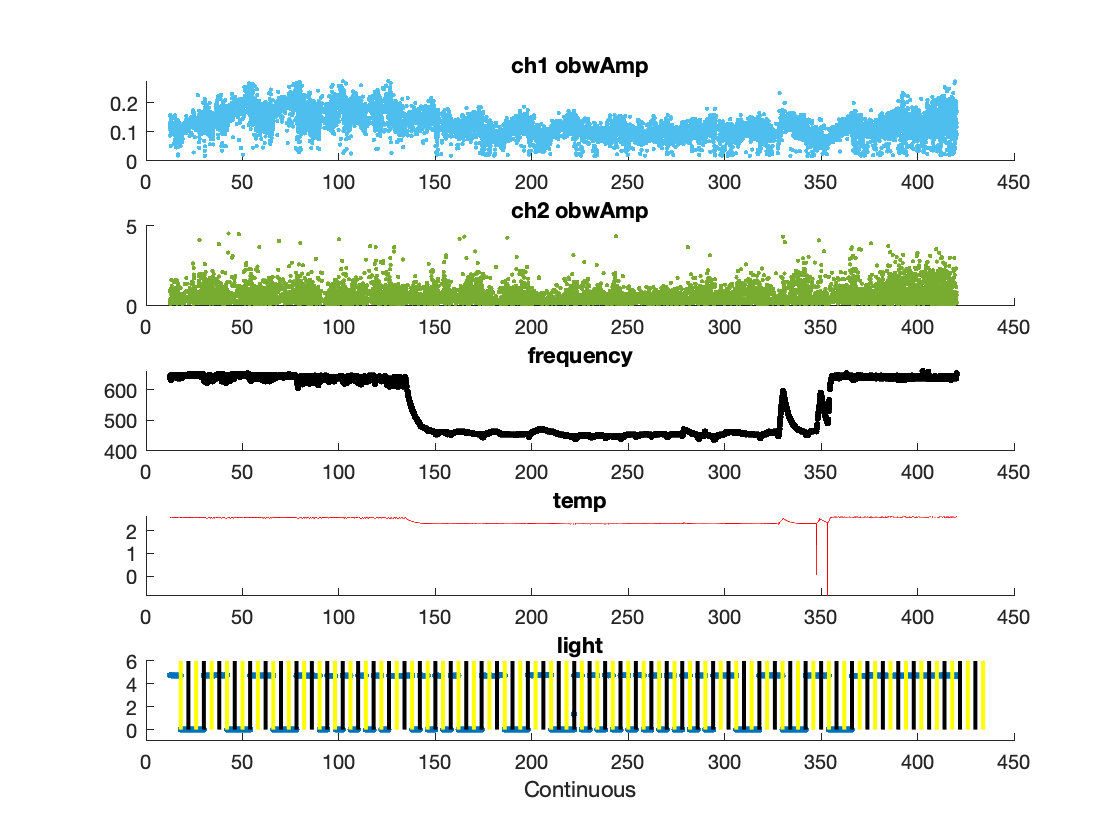

k_initialplotter(l24kg(k));

#### Remove outliers

Must be redone after trimming

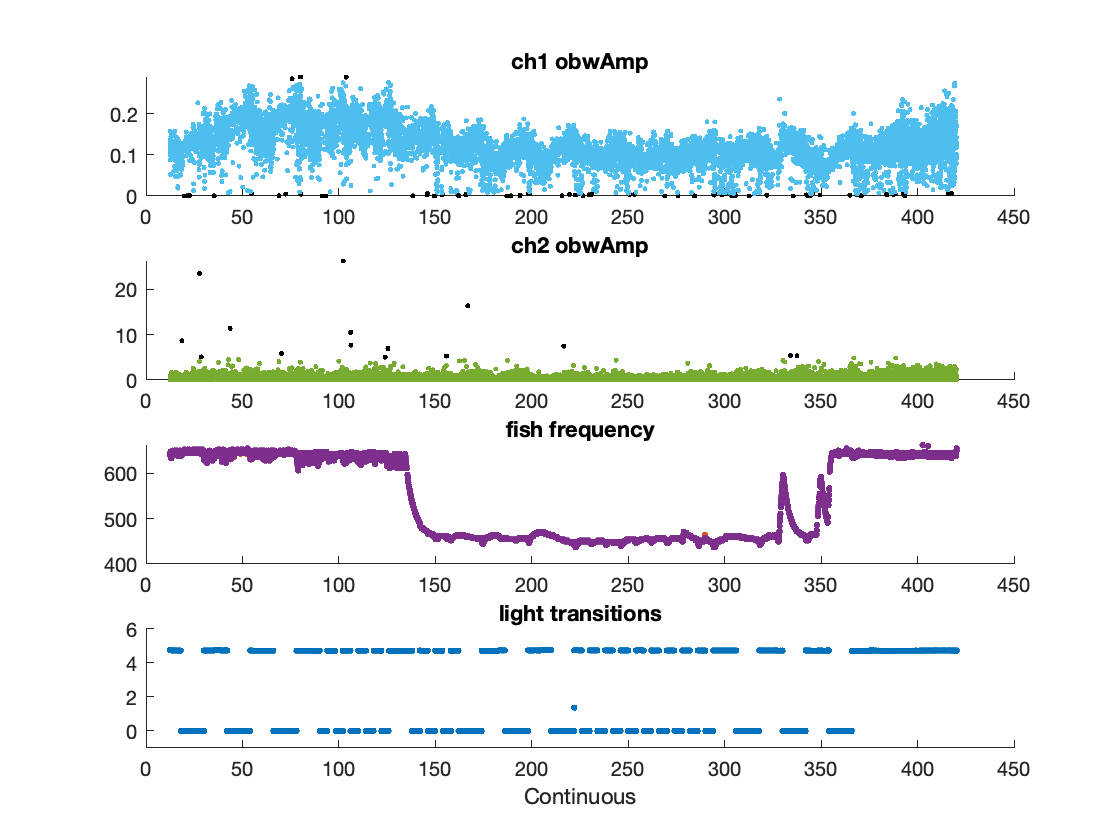

l24kg(k).idx = KatieRemover(l24kg(k).e);
k_removedsingleplotter(l24kg(k));

##  plot again

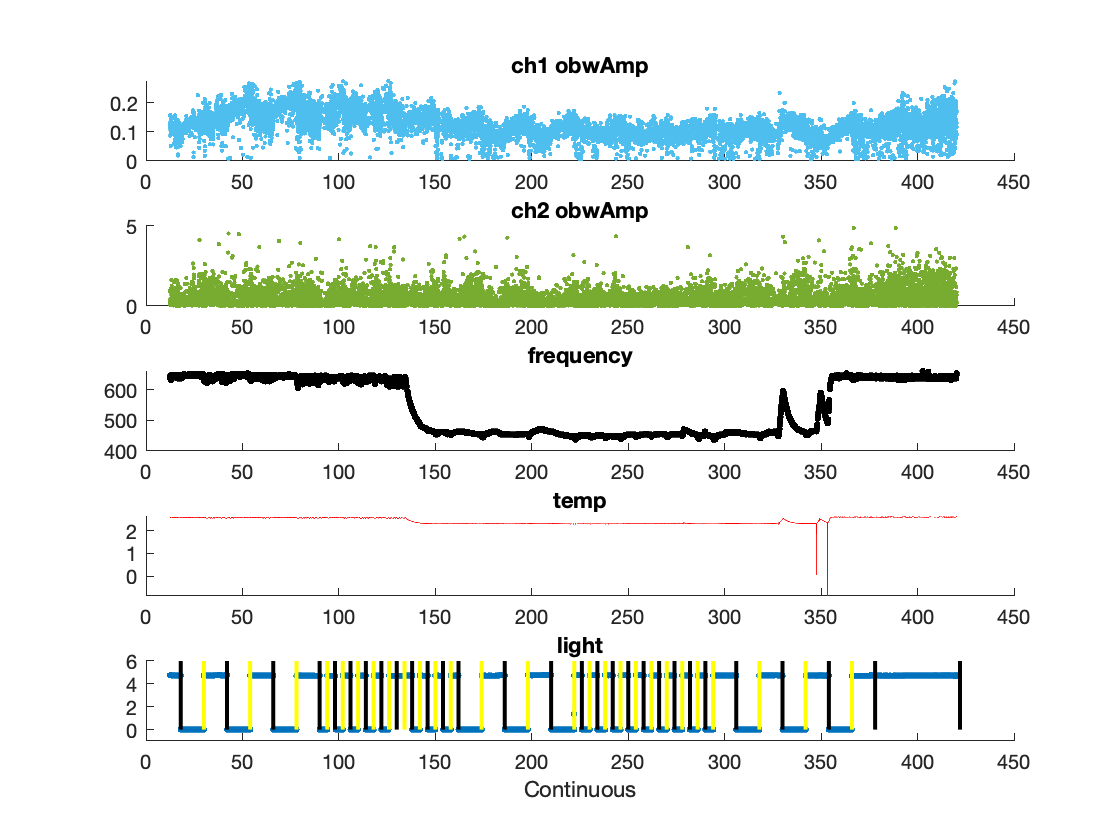

k_initialplotter(l24kg(k));

## label

l24kg(k).info = KatieTempLabeler(l24kg(k).e);

l24kg(k).info.luz = k_singlemanuallightlabeler(l24kg(k));

lidx = find(abs(l24kg(k).info.luz)< 102);
first12 = l24kg(k).info.luz(lidx);

lidx = find(abs(l24kg(k).info.luz)> 150 & abs(l24kg(k).info.luz)< 234);
second12 = l24kg(k).info.luz(lidx);

lidx = find(abs(l24kg(k).info.luz)> 293 & abs(l24kg(k).info.luz)< 390);
third12 = l24kg(k).info.luz(lidx);



lidx = find(abs(l24kg(k).info.luz)> 90 & abs(l24kg(k).info.luz)< 162);
first4 = -l24kg(k).info.luz(lidx);

lidx = find(abs(l24kg(k).info.luz)> 221 & abs(l24kg(k).info.luz)< 294);
second4 = -l24kg(k).info.luz(lidx);

l24kg(k).info.luz = [first12, first4, second12, second4, third12, -422]

l24kg = 1×75 struct array with fields:
    e
    info
    idx


lidx = find(abs(l24kg(k).info.luz)< 158);
l24kg(k).info.luz = l24kg(k).info.luz(lidx);

channel = 1;
    xidx = find([l24kg(k).e(channel).s.timcont]/3600 >26.42 & [l24kg(k).e(channel).s.timcont]/3600 < 33);
    for j = 1:length(xidx)
    l24kg(k).e(channel).s(xidx(j)).obwAmp = l24kg(k).e(channel).s(xidx(j)).obwAmp*6;
    end
